# Projecting a Shadow onto a Sphere

This library contains code for projecting a desired shadow shape onto a sphere.  This is called a stereographic projection.

The help you get started, there are also some tools for making fun 2D shapes.  These commands return a `polyshape` object.

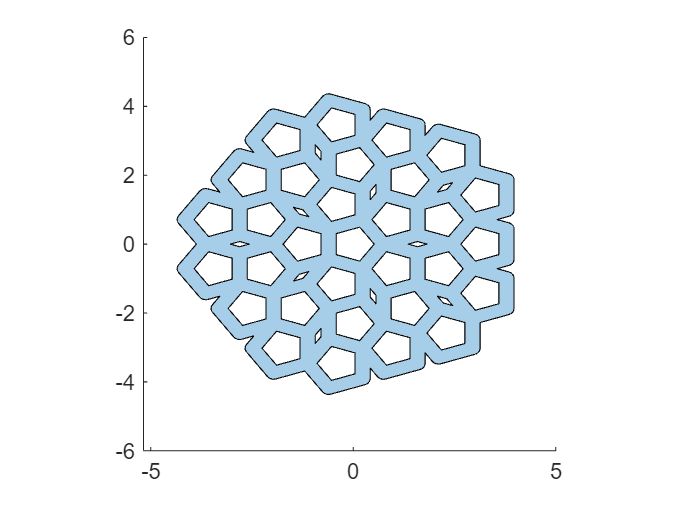

ps = shapegrid(5,4,'Radius',.75);

plot(ps);
axis square

Once you have a polyshape, you can project it onto a sphere.  The sphere is a 3D shape, so the utility returns a triangulation.

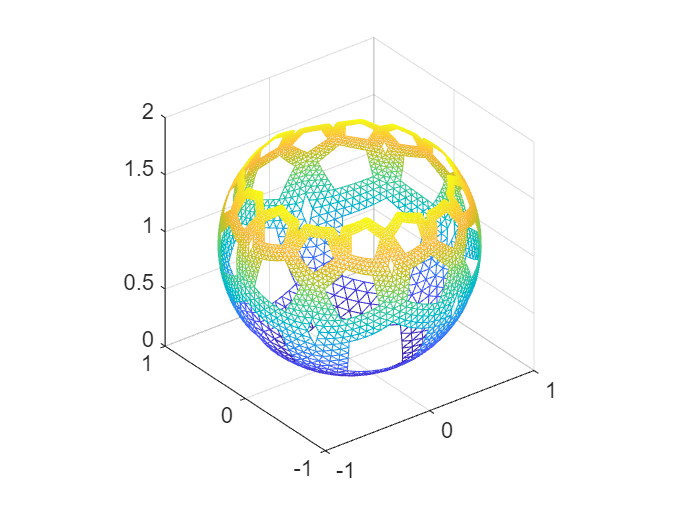

[tri, lz] = ps2stereographicsphere(ps);

trimesh(tri);
daspect([1 1 1]);

Now that we have a triangulation, we can visualize it with the `triMeshShadow` utility.  See `Examples_ProjectingShadows`.mlx to read more about that.  For this shape, we need to specify both the trianguation, and a light position, which is centered over the sphere at the Z position returned from the computation.

Use the Attenuation parameter to make the shadow fade out near the edges.

interp


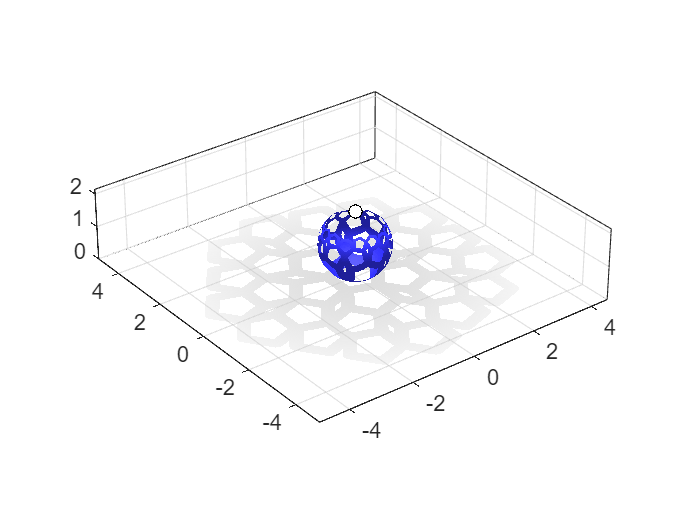

triMeshShadow(tri, [0 0 lz], 'Attenuation',6);

And now you can see that the original shape we selected is cast as a shadow on the floor of the Axes.

*Copyright 2024 The MathWorks, Inc.*